# Analysis of Robust Stability (RS) and Robust Performance (RP)

load statespace_data A B C D FWT

% 2 inputs, 2 outputs
s = tf('s');
G = FWT(1:2, 1:2);

% performance weights
wp = [(s/3+0.3*2*pi)/(s+pi*6e-5) 0;
    0 0.05];

wu = [0.005 0;
       0 (0.005*s^2 + 0.0007*s+0.00005)/(s^2 + 0.0014*s + 10^(-6))];

% uncertainty weights
wi1 = ((1/16*pi)*s + 0.3)/((1/64*pi)*s + 1);
wi2 = wi1;

wo1 = (0.05*s + 0.25)/(0.01*s + 1);
wo2 = wo1;

wi = [wi1 0;
      0 wi2];
wo = [wo1 0;
     0 wo2];

## 3. Frequency response of weights

% frequency response of uncertainty weights
figure
bodemag(wi)

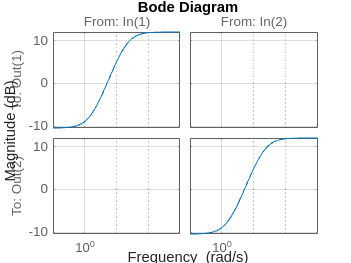

grid on

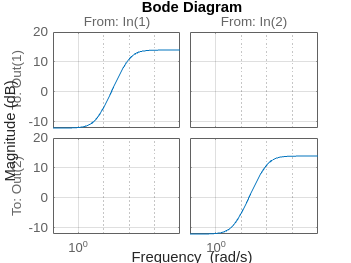


figure
bodemag(wo)
grid on


% uncertain TF singular values 

pb1 = ultidyn("idelta", 2)

Uncertain LTI dynamics "idelta" with 2 outputs, 2 inputs, and gain less than 1.
Block Properties


pb2 = ultidyn("odelta", 2)

Uncertain LTI dynamics "odelta" with 2 outputs, 2 inputs, and gain less than 1.
Block Properties


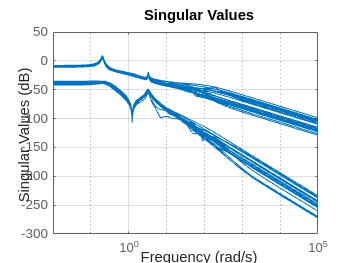


wid = wi*pb1;
wod = wo*pb2;

X = (eye(2)+wid)*G*(eye(2)+wod);

figure
sigma(X)
grid on

## 4. Augmented Generalised Plant

% Define plant and in- and outputs
G.u = 'udu';
G.y = 'y';

wp.u = 'v';
wp.y = 'z1';

wu.u = 'u';
wu.y = 'z2';

wo.u = 'y';
wo.y = 'do';

wi.u = 'u';
wi.y = 'di';

% Build system
sumblock1 = sumblk("ydy = y + dy", 2);
sumblock2 = sumblk("udu = u + du", 2);
sumblock3 = sumblk("v = w + ydy", 2);

dP = connect(G, wu, wp, wo, wi, sumblock1, sumblock2, sumblock3, {'w', 'u', 'du', 'du'}, {'z1', 'z2', 'v', 'do', 'di'});

## 5. Checking NS, NP, RS, RP

load mixedsensitivitycontroller.mat MS_C P CLms

K = MS_C

K =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1      -29.04       23.36      0.8346       1.528       1.288    -0.01752      -2.251      -105.6
   x2      -2.342       1.882      0.0157      0.1339      0.1069   -0.001976     -0.2198      -8.741
   x3  -2.378e-12           1  -1.978e-12   1.128e-13  -1.872e-12  -1.346e-15   -1.79e-13  -7.897e-12
   x4      -14.64       11.77      0.3481      0.7316      -10.15    -0.01235      -1.374      -54.63
   x5   5.727e-14  -4.594e-14   1.578e-14           1   1.322e-14   3.243e-17   4.312e-15   1.902e-13
   x6        13.3       -28.6      -4.516       -1.13     -0.4563     -0.1571      -9.422       44.41
   x7  -9.565e-17   7.673e-17   7.189e-18   4.539e-18   1.146e-17   0.0009766  -7.201e-18  -3.177e-16
   x8   1.036e-34  -7.028e-35   4.343e-19  -3.333e-37   4.343e-19   2.568e-37   2.047e-35  -0.0001885
 
  B = 
             v(1)        v(2)
   x1   2.569e-13    1.03e-14



% NS - generalised Nyquist
ol = K*G;
tdet = eye(2) - ol;

det = tdet(1,1)*tdet(2,2) - tdet(1,2)*tdet(2,1);

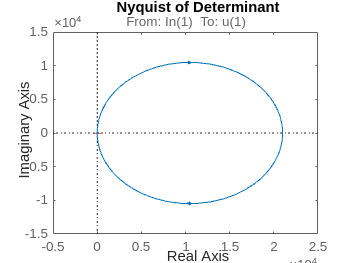


nyquist(det);
title('Nyquist of Determinant')


% NP - ||N||inf < 1
gamma = hinfnorm(CLms);

% RS 
% Build M
M11 = wi*K*G/(eye(2)- K*G);
M12 = wi*K/(eye(2)- K*G);
M21 = wo*G/(eye(2)- K*G);
M22 = wo*K*G/(eye(2)- K*G);

M = [M11 M12;
    M21 M22];

% frequencies to check and shape of Delta block
omega=logspace(-3,4,70);
Mf=frd(M,omega);
blockstructure =  -ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 70/70



% norm of bound
muRS = mubnds(:,1);
[muRSinf, muRSw] = norm(muRS,inf);
muRSinf

muRSinf = 2.1022


% RP
% Build N
N13 = wi*K/(1-G*K);
N23 = wo*G*K/(1-G*K);
N31 = wp*K*G/(1-G*K);
N32 = wp/(1-G*K);
N33 = wp/(1-G*K);
N41 = wu*K*G/(1-G*K);
N42 = wu*K/(1-G*K);
N43 = wu*K/(1-G*K);

N = [M11 M12 N13;
    M21 M22 N23;
    N31 N32 N33;
    N41 N42 N43];


% Evaluate at frequencies and decide structure on uncertainty
Nf = frd(N,omega);

blockstructureN =  [blockstructure;
    2 4];

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Nf, blockstructureN);

Points completed: 70/70



% norm of bound
muRP = mubnds(:,1);
[muRPinf, muRPw] = norm(muRP,inf);
muRPinf

muRPinf = 4.5156e+05